# **Example: Deep Neural Network-Based Approximation of Nonlinear Model Predictive Control: Applications to Truck-Trailer Control Systemd**

**Date: **25.06.24

**Corresponding Author: **Kyoungseok Han (kyoungsh@hanyang.ac.kr), Hanyang University

**Author: **Suyong Park (suyongpark@hanyang.ac.kr), Hanyang University

**Description: **This script implements a closed-loop MPC controller for a truck-trailer vehicle following a reference path. The controller minimizes tracking errors while respecting physical constraints. If you find this code helpful, we kindly ask that you cite the following reference: [**https://link.springer.com/article/10.1007/s12555-024-0475-2**](https://link.springer.com/article/10.1007/s12555-024-0475-2)

**Requirements:**

- MATLAB R2020b or later

- Acados toolbox ([https://docs.acados.org/list_of_projects/index.html](https://docs.acados.org/list_of_projects/index.html))

- CMake ([https://cmake.org/download/](https://cmake.org/download/))

- MinGW-w64 (MATLAB add-on)

# **STEP3: Approximation of NMPC**

The control input (steering angle) is saved based on the initial state of the truck-trailer in Step 2. Since all possible truck-trailer pose data is collected using NMPC, an approximation of NMPC is implemented in Step 3 to reduce its computational burden. The raw data is stored in the file data_collection_final.mat file. The input layer of the neural network corresponds to the initial truck-trailer pose$\left\lbrace \theta_{\mathrm{hf}} ,\theta_{\mathrm{tf}} ,e_{f,h} \right\rbrace$, and the output layer represents the steering angle$\left(\delta \right)\ldotp$ A feedforward neural network (DNN) is selected to approximate the behavior of NMPC.

To accurately compare the approximation results with NMPC, the same NMPC formulation used in Step 2 must be applied for data collection and result comparison. The data_collection_final.mat should be used for reference only.

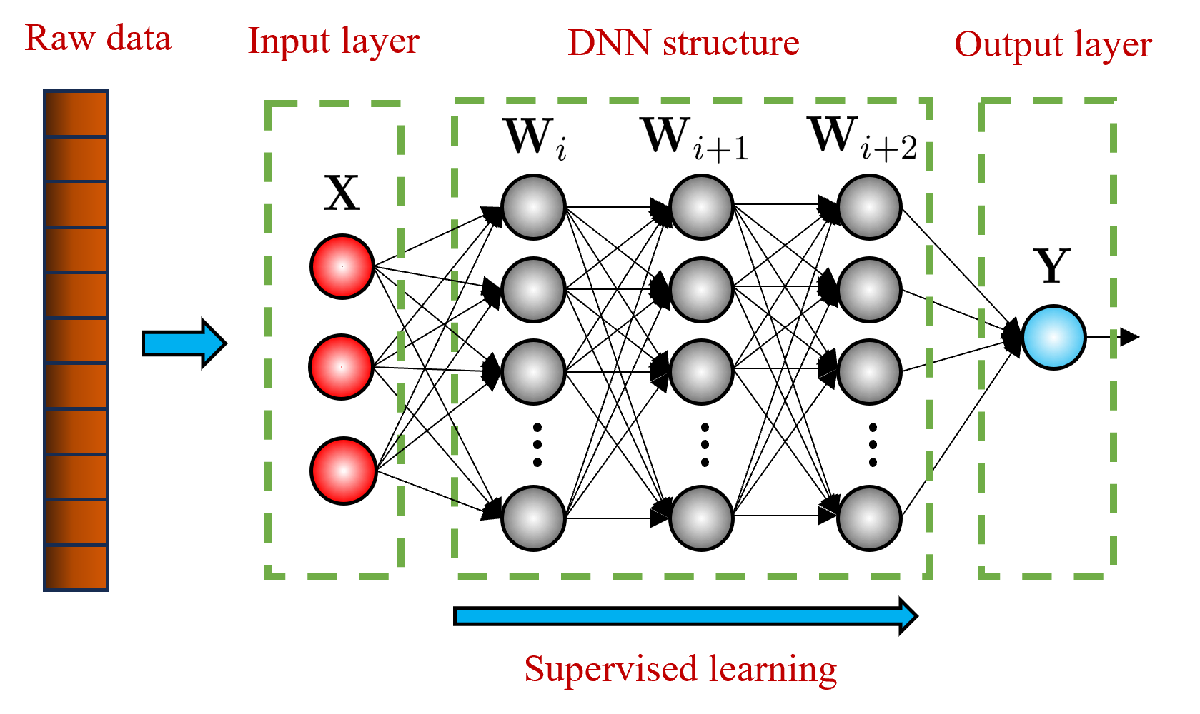

## Define parameters

x_nn_train_v and y_nn_train_v represent the input and output layers, respectively. The training times (maxTrials_primal_fixedStructure_v) and the maximum number of structure changes (maxTrials_primal_changedStructure_v) need to be determined to obtain the best-trained DNN structure. For example, if maxTrials_primal_changedStructure_v = 3, the number of neurons in each layer (defined by primalNetworkSize_v) can be adjusted up to three times. All trained networks are saved, and the one with the lowest mean square error (MSE) is selected as the best model. Hyperparameters such as the number of epochs, layers, neurons, and activation functions can be defined by the user.

clear all; close all; clc
load data_collection_final.mat

% define input and output layer
x_nn_train_v = [x0_history_collection(3,:);x0_history_collection(6,:);x0_history_collection(7,:)];
y_nn_train_v = [u_history_collection];

% traning times and maximum structuer changing
maxTrials_primal_fixedStructure_v = 3;      % training times for 1 fixed NN structure
maxTrials_primal_changedStructure_v = 1;    % maximum structure changing
net_primal_v = cell(1,1);
trialNumber_addNeur_v = 1;  % counter

% % Store all runs
netPrimal_all_v = cell(maxTrials_primal_fixedStructure_v,maxTrials_primal_changedStructure_v);
netPrimal_perf_all_v = nan(maxTrials_primal_fixedStructure_v,maxTrials_primal_changedStructure_v);

% % Initial primal network parameters
tr_mse_v = inf;
primalNetworkSize_v = [20 20 20 17]; % layer and nerons
tmp_v = sqrt(sum(y_nn_train_v.^2,1)); 
eps_mse_v = 1e-5*max(tmp_v);

## Training

The DNN is trained for the number of epochs specified by net_primal_v.trainParam.epochs using the current network structure. Among the trained models, the one with the lowest mean square error (MSE) is selected. This process is repeated until the number of trials reaches maxTrials_primal_changedStructure_v.

%% Start training
while (tr_mse_v > eps_mse_v)&&(trialNumber_addNeur_v <= maxTrials_primal_changedStructure_v)
    
    disp(['network size: ', num2str(primalNetworkSize_v)]);
    trialNumber_fixedStruct_v = 0;
    for ii = 1 : maxTrials_primal_fixedStructure_v
        trialNumber_fixedStruct_v = trialNumber_fixedStruct_v + 1;
        disp(['trial number with fixed structure: ', num2str(trialNumber_fixedStruct_v)]);

        % % Define the neural network
        net_primal_v = feedforwardnet(primalNetworkSize_v);

        % net_primal_v = cascadeforwardnet(primalNetworkSize_v);
        net_primal_v.layers{1}.transferFcn = 'poslin';
        net_primal_v.layers{2}.transferFcn = 'poslin';
        net_primal_v.layers{3}.transferFcn = 'poslin';
        net_primal_v.divideParam.trainRatio = 70/100;
        net_primal_v.divideParam.valRatio = 10/100;
        net_primal_v.divideParam.testRatio = 20/100;

        % % Number of epochs
        net_primal_v.trainParam.epochs = 500;
        [net_primal_v, tr_v] = train(net_primal_v,x_nn_train_v,y_nn_train_v,'useGPU','no');

        % % obtaining the MSE for the best epoch
        tr_mse_v = tr_v.perf(tr_v.best_epoch+1);
        netPrimal_perf_all_v(trialNumber_fixedStruct_v,trialNumber_addNeur_v) = tr_mse_v;
        netPrimal_all_v{trialNumber_fixedStruct_v,trialNumber_addNeur_v} = net_primal_v;

        % % Display
        disp(['training error: ', num2str(tr_mse_v)]);
        disp(['best training error so far: ', num2str(min(min(netPrimal_perf_all_v)))]);

        % % check if the desired mse has been reached
        if tr_mse_v <= eps_mse_v
            disp(['----> Success!   | network size: ',num2str(primalNetworkSize_v), '    |  MSE: ', num2str(tr_mse_v)]);
            break
        end
    end
    primalNetworkSize_v = primalNetworkSize_v + 5;
    trialNumber_addNeur_v = trialNumber_addNeur_v + 1;
    disp(['Neuron Increase Index: ', num2str(trialNumber_addNeur_v)]);
    end

network size: 20  20  20  17


trial number with fixed structure: 1


## Select best trained network

Among multiple DNN structures, the network with the lowest MSE is selected and converted into a MATLAB function. By providing the input values defined in the input layer of the MATLAB function, the corresponding steering angle for NMPC is calculated as the output.

%% Pick the best trained network (with lowest MSE)
min_mse_v = min(min(netPrimal_perf_all_v));
[idx1_v, idx2_v] = find(netPrimal_perf_all_v==min_mse_v);
net_primal_v = netPrimal_all_v{idx1_v,idx2_v};

% gen MATLAB function
genFunction(net_primal_v,'primalNet_ex','MatrixOnly','yes');
% export to c code with mex interface
inputType = coder.typeof(double(0),[1 1]); % specify input type
codegen primalNet_ex -config:mex -o pNet_v_CodeGen -args inputType
% save all data
save('primalNet_training_ex.mat')

% call script to train space net
%Step3_approxMPC_primalNet_training_space